# 关于第二次编程作业的说明：

- 请注意完成编程作业中的讨论，可以通过注释、嵌入文本、额外文件等任意形式完成；

- 在第二次编程作业中如果使用工具箱，可以通过截图等形式提交结果；

- 为了简化大家的代码过程，我向大家提供了第二次编程作业的.mlx文件，里面提供了关于.mlx文件的说明以及部分同学在第一次编程作业中使用.mlx文件时遇到的图像错位问题；

- 大家仍然可以使用任意形式matlab代码完成第一次编程作业，并不限制大家一定需要使用该模版，但仍然需要大家注明题号；

感谢大家的配合！

# template

- 本文件已经对每道编程题目通过分节符分节，可以单独通过”运行节“命令执行一道题目（选中）的代码，或通过”运行“命令执行整个文件；

- 关于很多同学在.mlx中遇到的图像错位问题：主要原因是在单个脚本文件中，工作区和图像设定是始终向后保持的。在之前的题目中使用subplot()画多个子图，之后的题目中画图时会出现在之前的子图中，可以在每个题目的代码前通过clf命令清除图像窗口；

clear
clf

% (a)
x = 0:pi/100:2*pi;  
y = sin(x)
plot(x,y), grid;
% (b)
% 讨论分析

或通过内置文本讨论分析。如需插入公式，可以使用方程或LaTex方程 $F(s)=\int_0^\infty e^{-st} f(t) {\rm d}t$。

如需插入截图，直接粘贴即可。

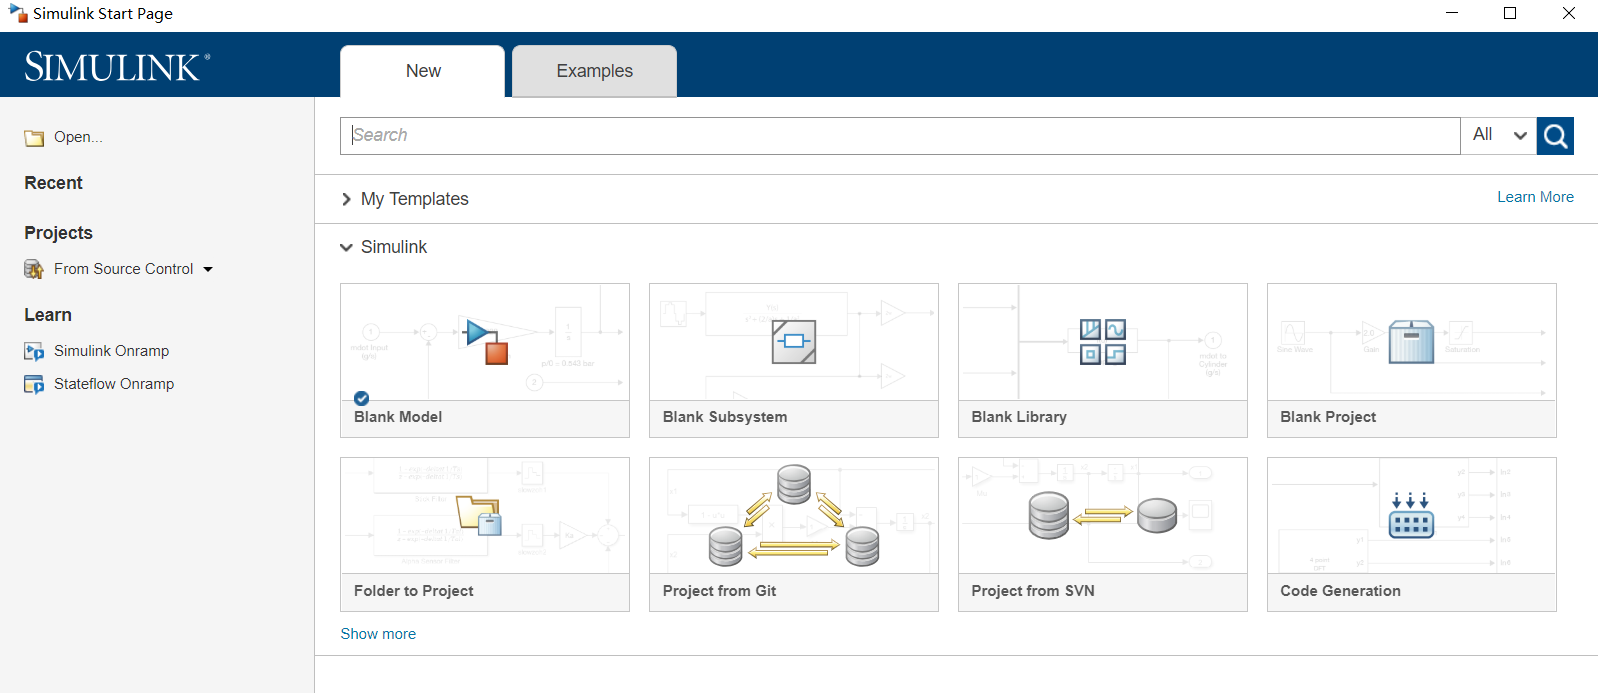

# 7-1

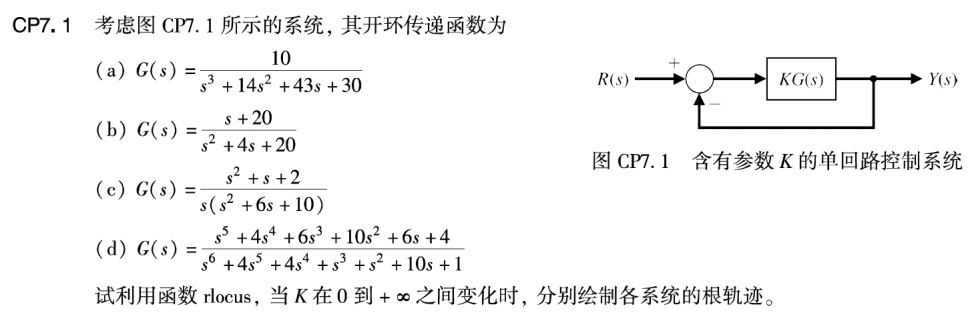

clear
clf
sys1=tf([10],[1 14 43 30]);
rlocus(sys1)
sys2=tf([1 20],[1 4 20]);
rlocus(sys2)
sys3=tf([1 1 2],[1 6 10 0]);
rlocus(sys3)
sys4=tf([1 4 6 10 6 4],[1 4 4 1 1 10 1]);
rlocus(sys4)

# 7-2

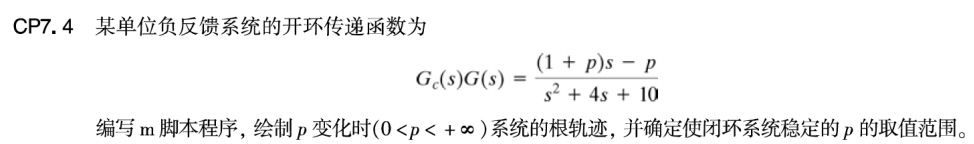

等价闭环特征方程为$1+\frac{p(s-1)}{s^2+5s+10}=0$


$$用等价特征方程建立劳斯判据\\
s^2\ |\ 1\ 10-p\\
s^1\ |\ 54+p\ 0\\
s^0\ |10-p\\
因此0<p<10$$


clear
clf
sys1=tf([1 -1],[1 5 10]);
rlocus(sys1)
 

# 7-3

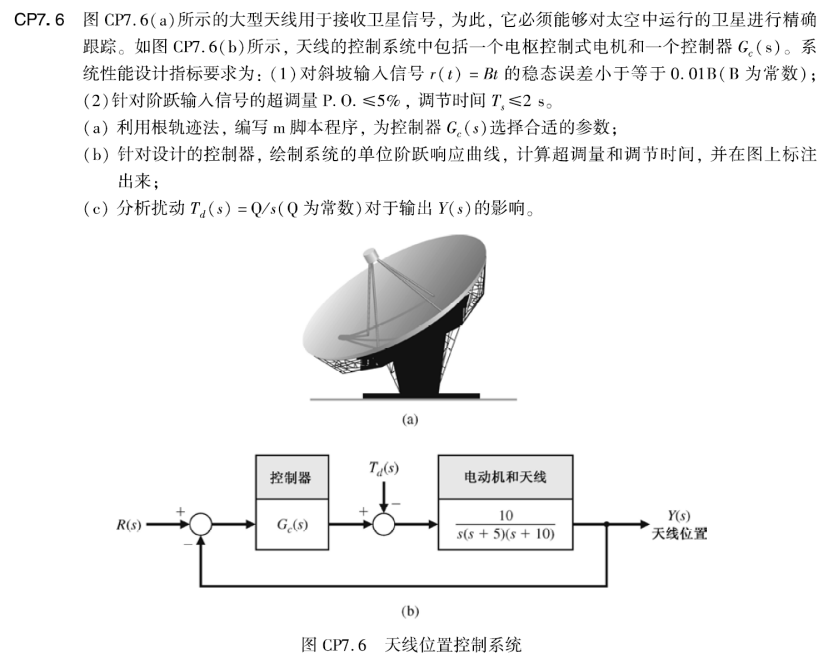

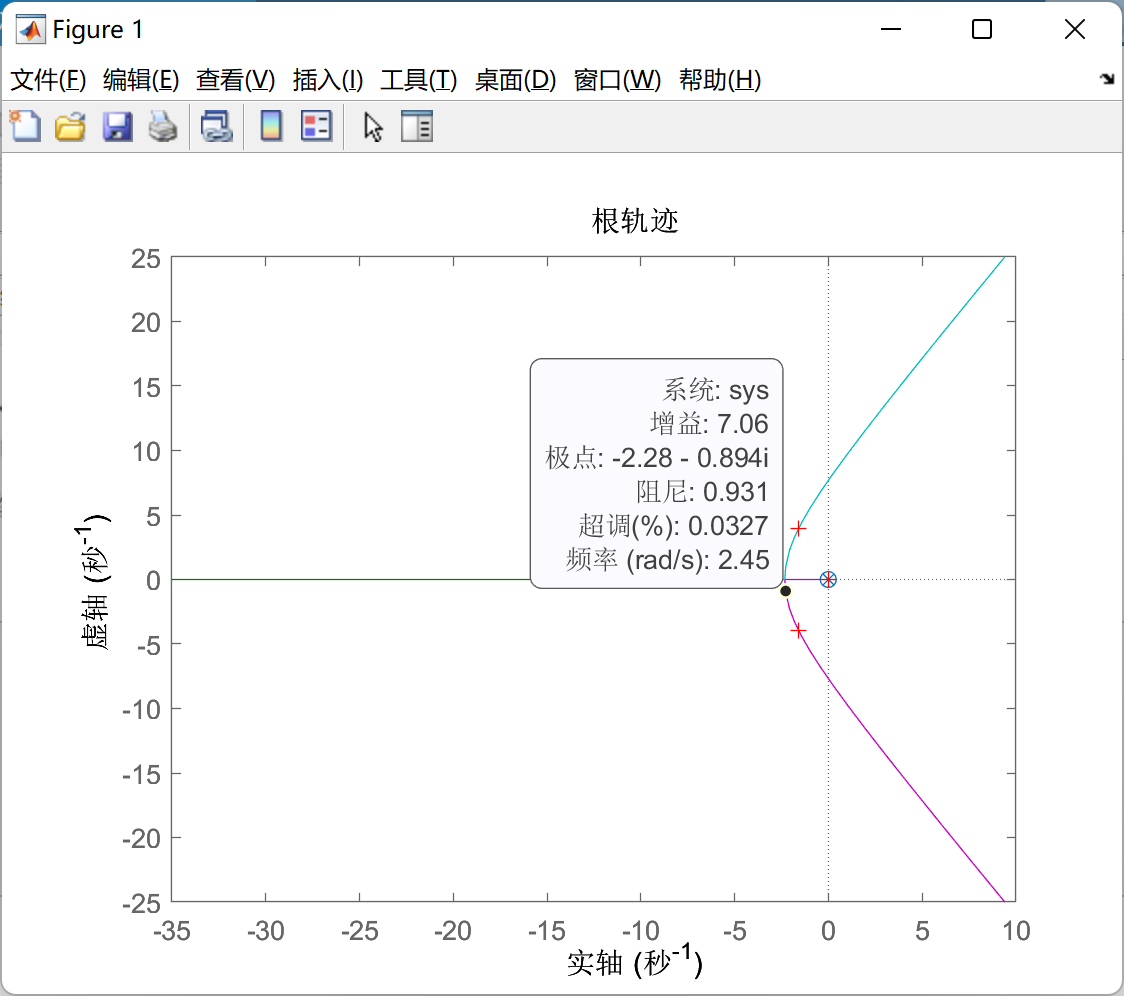

挑选的增益K=7.06，满足要求

计算出斜坡响应的Kv=119.4769

对应稳态误差为0.0084<0.01

clear
clf
sysg=tf([10],[1 15 50 0]);
nh=conv([1 0.01],[1 5.5]);
dh=conv([1 6.5],[1 0.0001]); 
sysh=tf(nh,dh);
sys=sysg*sysh;
rlocus(sys)
% rlocfind(sys)
K=7.06; sysh=tf(K*nh,dh);
sys=series(sysg,sysh);syscl=feedback(sys,1);

step(syscl);
Kv=10*7.06*0.01*5.5/10/6.5/0.0001/5
e=1/Kv
systd=feedback(sysg,sysh);
step(systd)

# 7-4

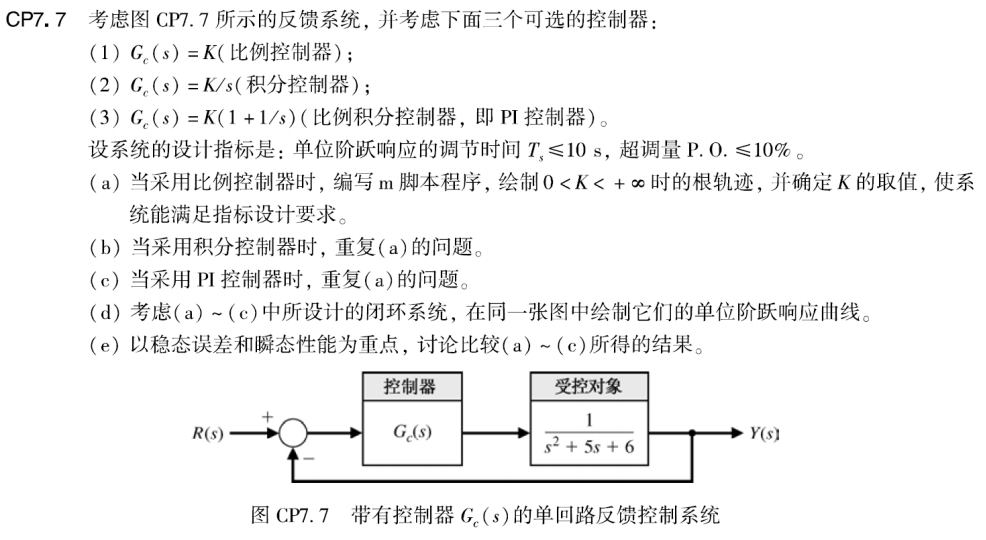

(a)

k1=11.1

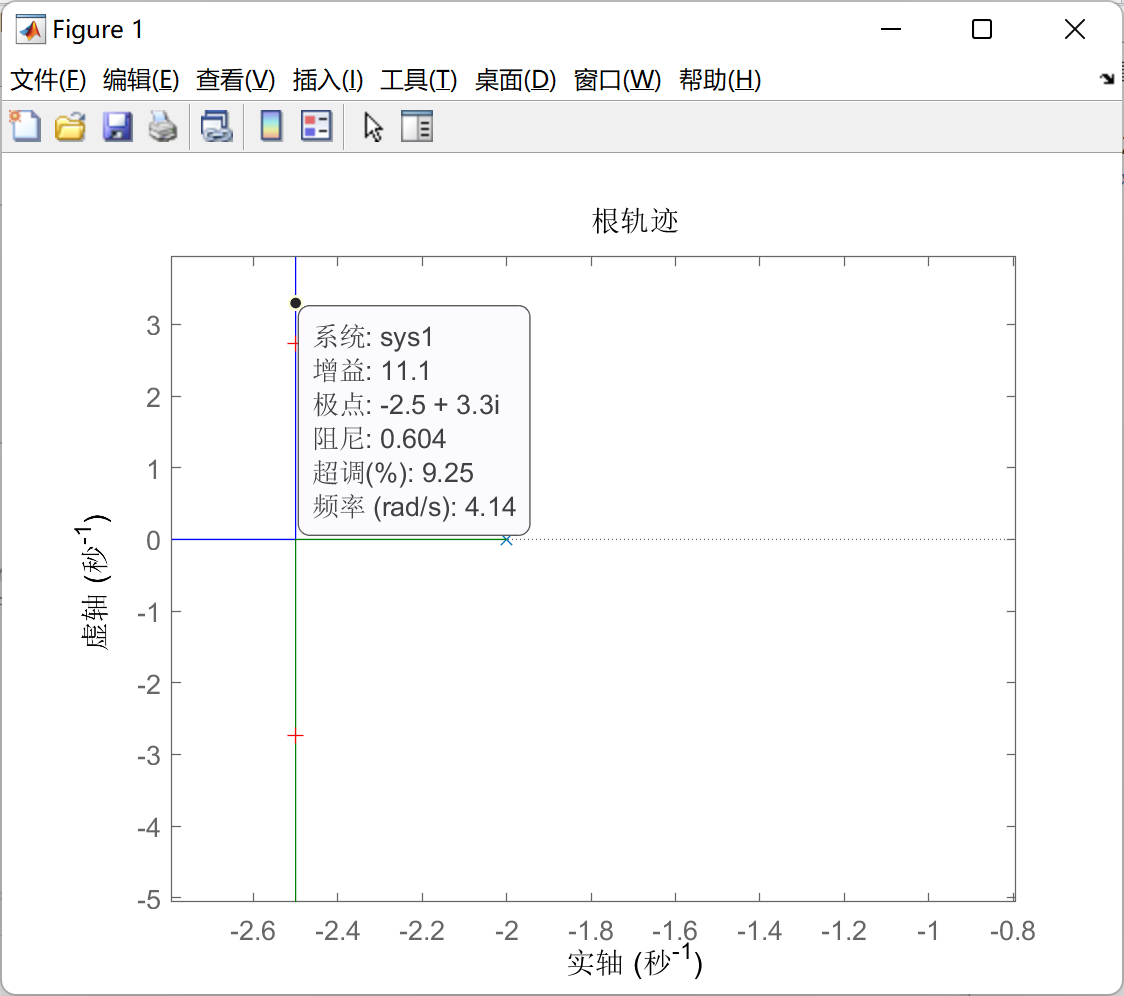

(b)

k2=4.44

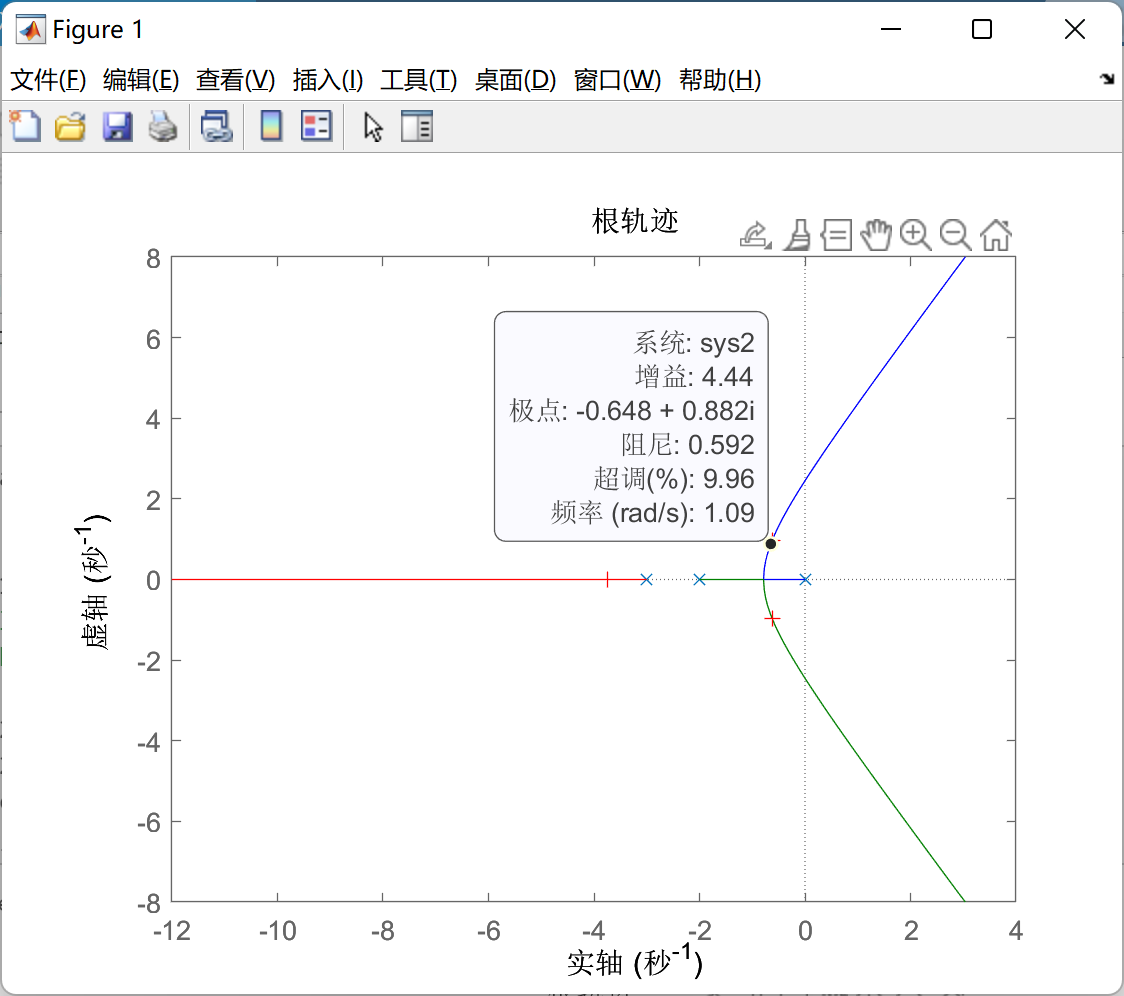

(c)

k3=9.29

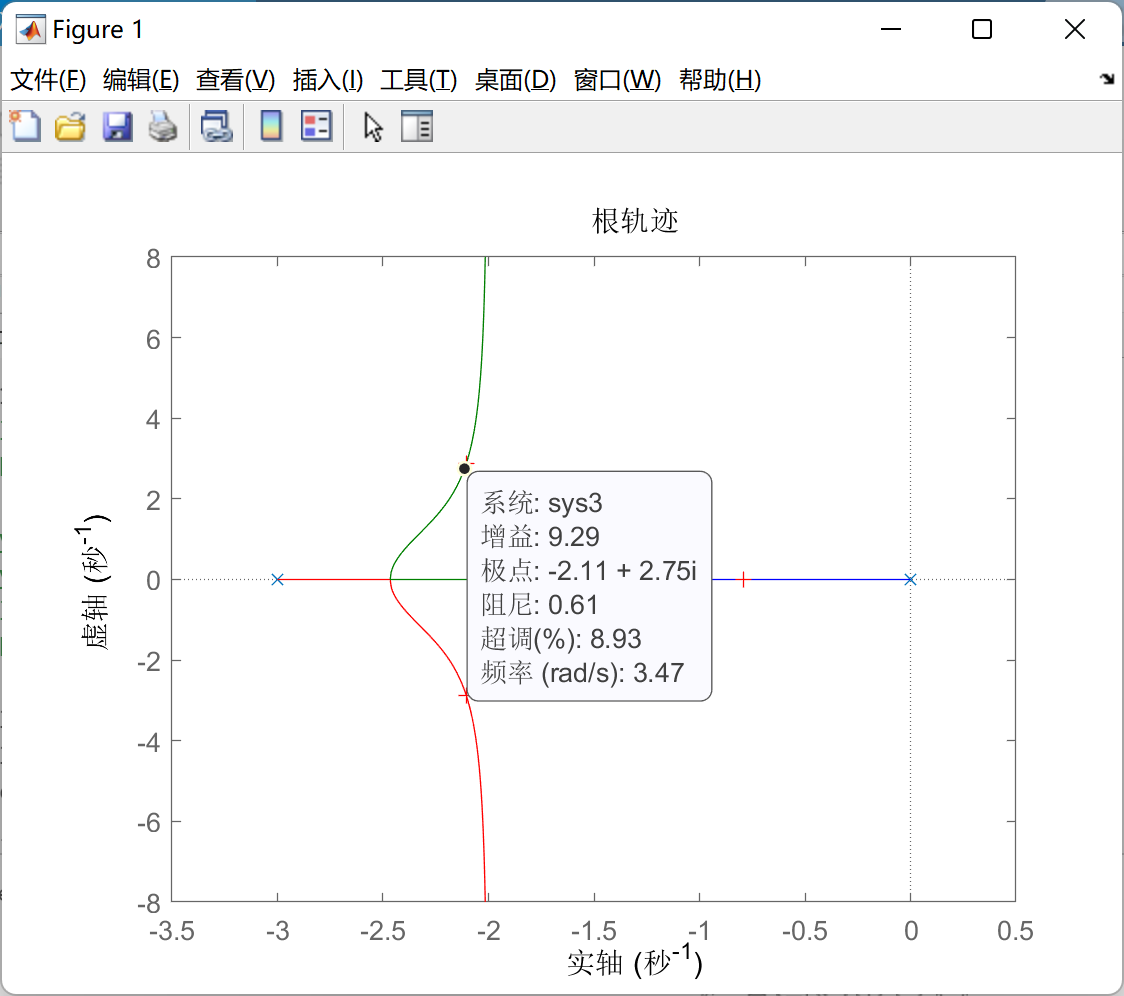

(e)分析：

1、P控制器对所有的K都很稳定，但稳态误差比较大

2、I控制器没有稳态误差，但只在K<30时是稳定的

3、PI控制器对所有的K都很稳定，没有稳态误差，且阶跃响应也很快

clear
clf
%a
sys1=tf([1],[1 5 6]);
% rlocus(sys1)
% [k1,poles] = rlocfind(sys1)
%b
sys2=tf([1],[1 0]);
sys2=series(sys2,sys1);
% rlocus(sys2)
% [k2,poles] = rlocfind(sys2)
%c
sys3=tf([1 1],[1 0]);
sys3=series(sys3,sys1);
% rlocus(sys3)
% [k3,poles] = rlocfind(sys3)
%d
t=[0:0.1:15];
k1=11.1;k2=4.44;k3=9.29;
sys1_o = k1*sys1; sys1_cl = feedback(sys1_o,[1]);
sys2_o = k2*sys2; sys2_cl = feedback(sys2_o,[1]);
sys3_o = k3*sys3; sys3_cl = feedback(sys3_o,[1]);
[y1,t]=step(sys1_cl,t);
[y2,t]=step(sys2_cl,t);
[y3,t]=step(sys3_cl,t);
plot(t,y1,t,y2,'--',t,y3,':'),grid

# 7-5

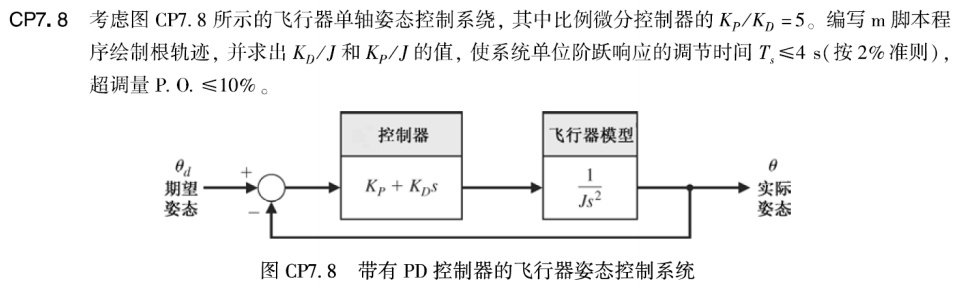

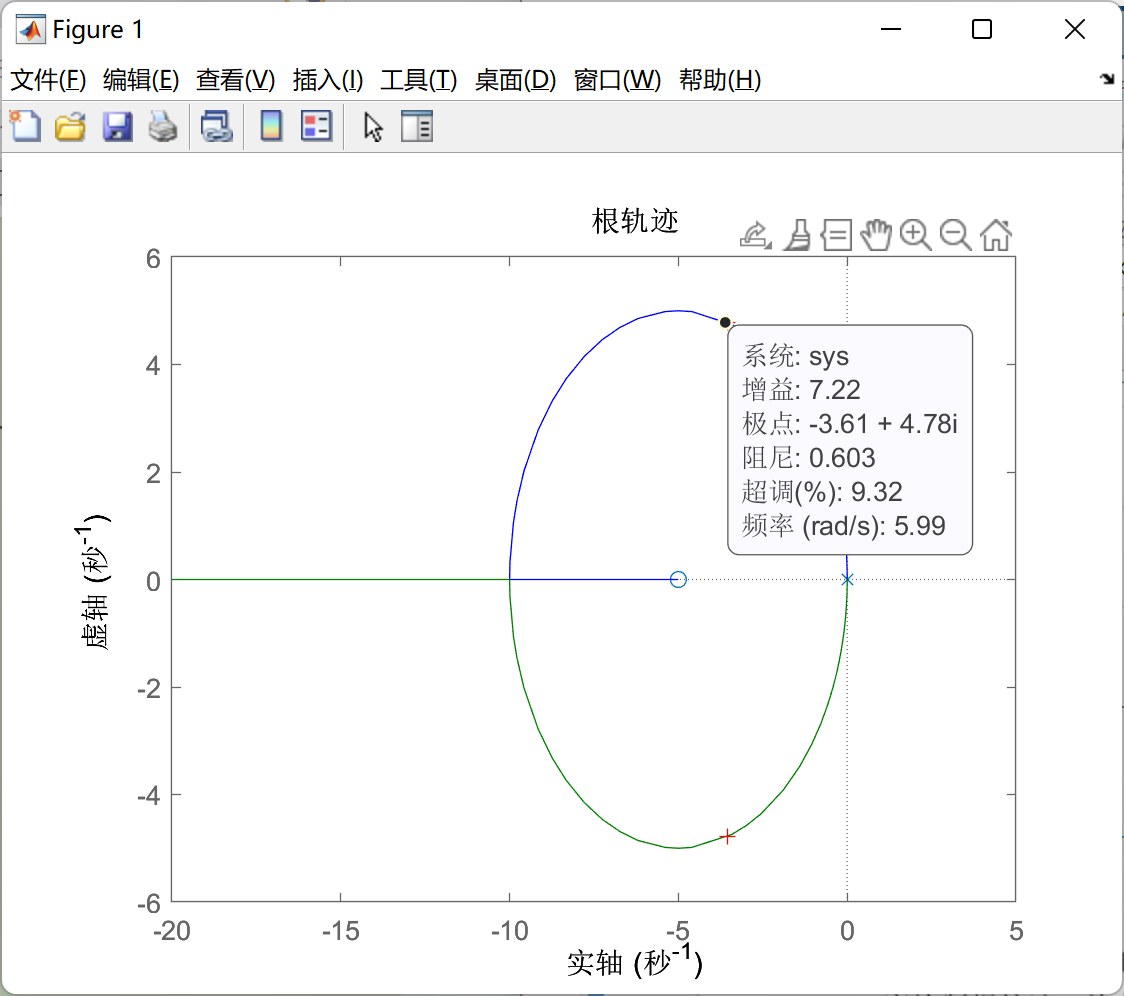

K2/J=7.22

K1/J=36.1

clear
clf

sys=tf([1 5],[1 0 0]);
rlocus(sys)
% [k,poles] = rlocfind(sys)

# 7-6

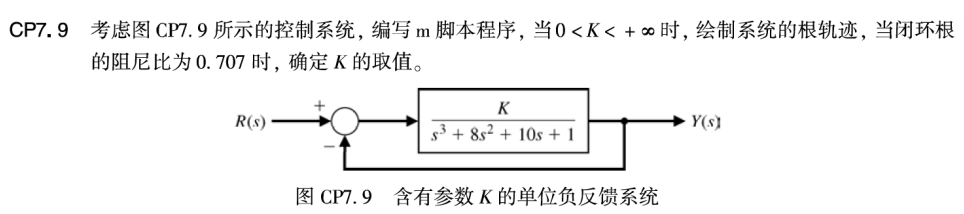

clear
clf

sys=tf([1],[1 8 10 1]);
rlocus(sys)
%解出K=5.2

# 3-1

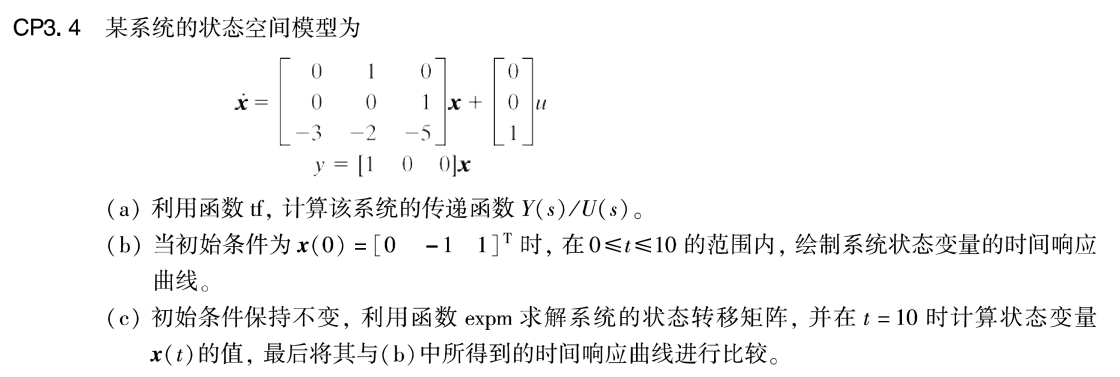

clear
clf

%a
A=[0 1 0; 0 0 1; -3 -2 -5];
B=[0 ;0 ;1];
C=[1 0 0 ];
D=[0];
sys=ss(A,B,C,D);

sys_tf=tf(sys)
%b
x0=[0 -1 1];
t=[0:0.1:10];
u=0*t;
lsim(sys,u,t,x0)
%c
dt=[10];
phi=expm(A*dt)
x_phi=phi*x0'%转置一下

# 3-2

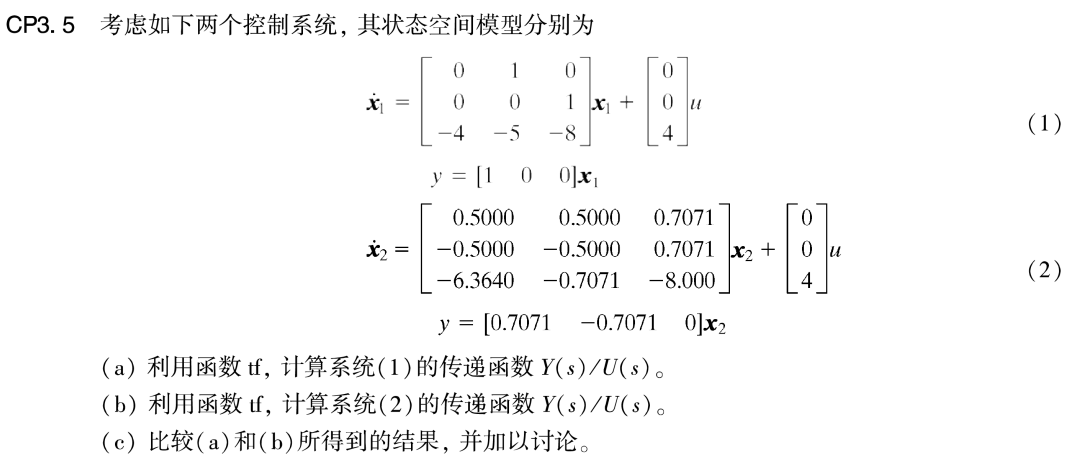

clear
clf

a1=[0 1 0; 0 0 1; -4 -5 -8];
b1=[0;0;4];
c1=[1 0 0];
d1=[0];
%(a)
sys_ss = ss(a1,b1,c1,d1);
sys_tf = tf(sys_ss)
%(b)
a2=[ 0.5000 0.5000 0.7071;
 -0.5000 -0.5000 0.7071;
 -6.3640 -0.7071 -8.0000];
b2=[0;0;4];
c2=[0.7071 -0.7071 0];
d2=[0];
sys_ss = ss(a2,b2,c2,d2);
sys_tf = tf(sys_ss)
%
%结果相同，这说明不同的状态空间方程之间可能等价

# 3-3

clear
clf

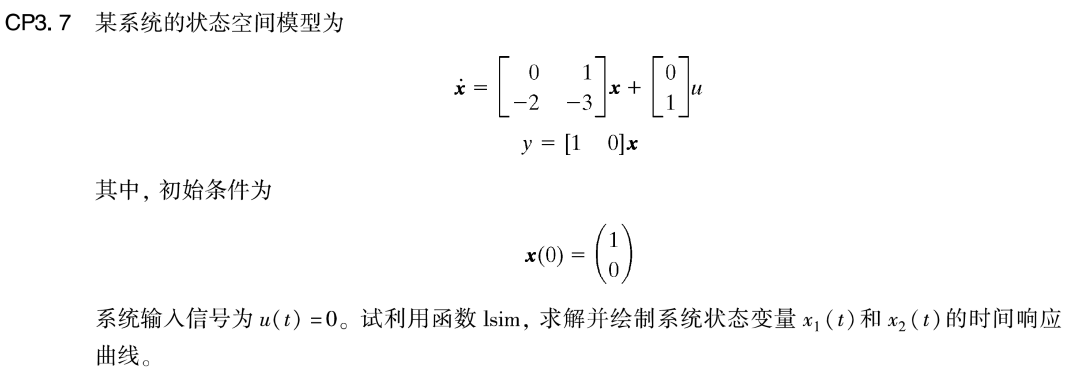


a=[0 1;-2 -3]; b=[0;1]; c=[1 0]; d=[0];
sys = ss(a,b,c,d);
x0=[1;0];
t=[0:0.1:10]; u=0*t;
[y,t,x]=lsim(sys,u,t,x0);
plot(t,x(:,1),t,x(:,2),'--')

# 11-1

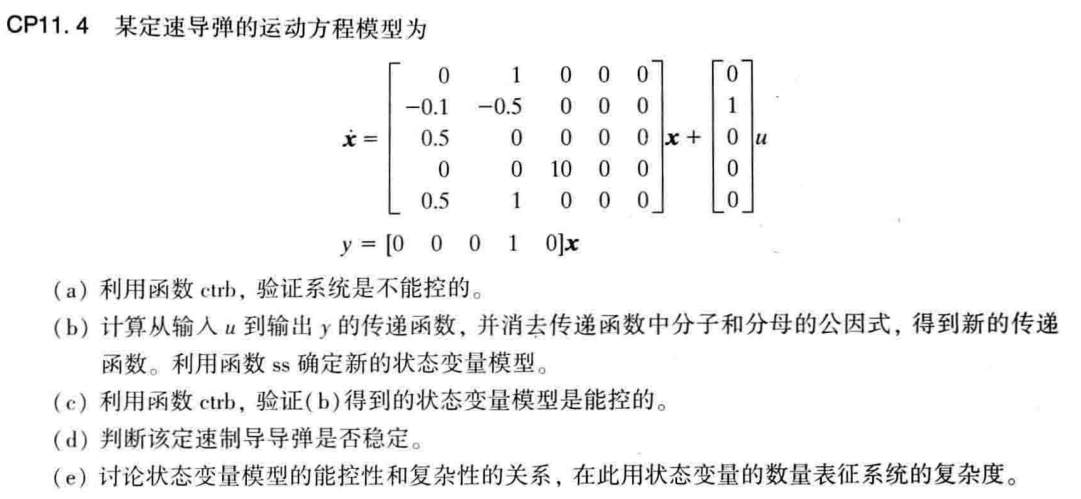

clear
clf

%a
A=[0 1 0 0 0;-0.1 -0.5 0 0 0;0.5 0 0 0 0;0 0 10 0 0;0.5 1 0 0 0];
b=[0;1;0;0;0];
c=[0 0 0 1 0];
d=[0];
sys_ss = ss(A,b,c,d);
Co=ctrb(sys_ss); 
dt_Co=det(Co)
%b
sys_tf = tf(sys_ss)
sys_new = minreal(sys_tf );%消去公因式
sys_new_ss=ss(sys_new)
%c
Co_new=ctrb(sys_new_ss); dt_Co_new=det(Co_new)
%d
pzmap(sys)
 eig(A)
%因此能控但不稳定，因为有两个极点
%e
%不可控的系统有很多状态，消去了不必要的状态（公因式）后，复杂性降低

# 11-2

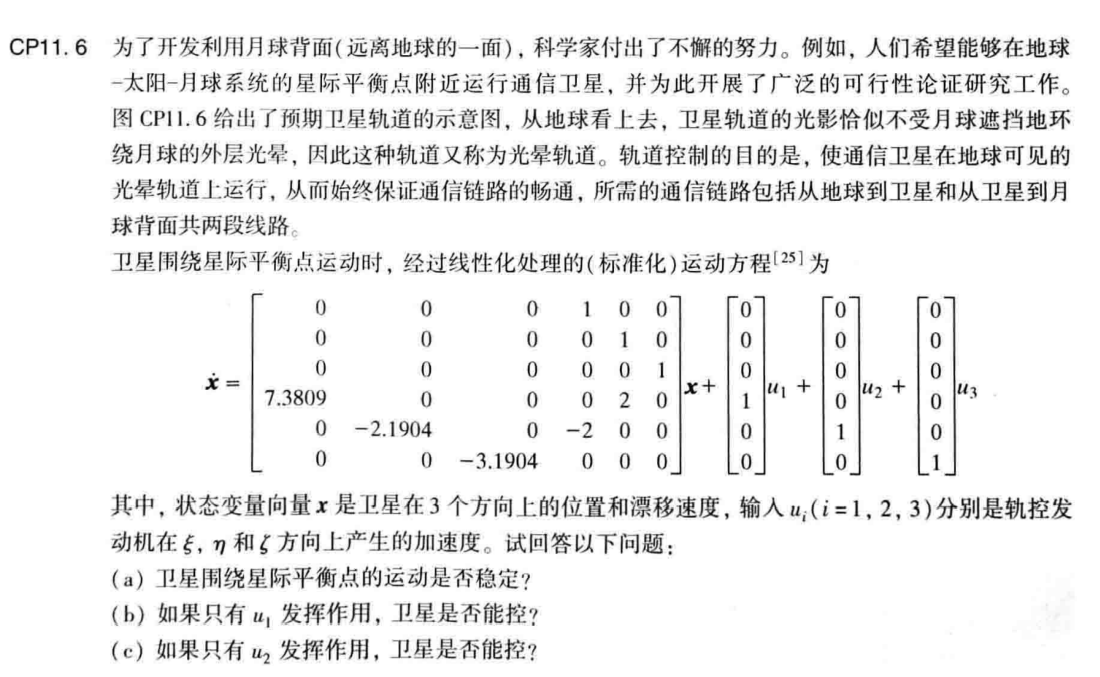 

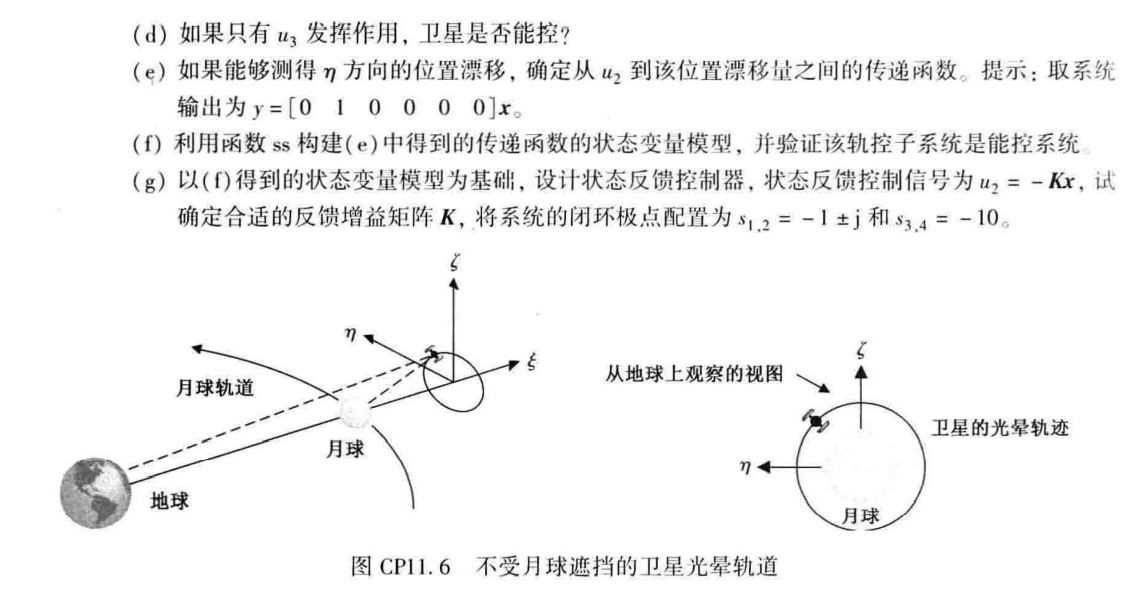

clear
clf

A=[0 0 0 1 0 0;0 0 0 0 1 0; 0 0 0 0 0 1;7.3809 0 0 0 2 0;
 0 -2.1904 0 -2 0 0; 0 0 -3.1904 0 0 0];

c=[0 1 0 0 0 0];d=[0];
b1=[0;0;0;1;0;0];
b2=[0;0;0;0;1;0];
b3=[0;0;0;0;0;1];
sys_ss_1 = ss(A,b1,c,d);
sys_ss_2 = ss(A,b2,c,d);
sys_ss_3 = ss(A,b3,c,d);

%a
eig(A)
%右半平面有点，不稳定
%b:不能控
Cb1=ctrb(sys_ss_1); dt1=det(Cb1)
%c:不能控
Cb2=ctrb(sys_ss_2); dt2=det(Cb2)
%d:不能控
Cb3=ctrb(sys_ss_3); dt3=det(Cb3)
%e
sys_tf = tf(sys_ss_2);
sys_tf=minreal(sys_tf )
%f
sys_ss=ss(sys_tf );
Co=ctrb(sys_ss); dt_Co=det(Co)
%g
P = [-1+i; -1-i;-10;-10];
[A,B]=ssdata(sys_ss);%ssdata
K = acker(A,B,P)

# 11-3

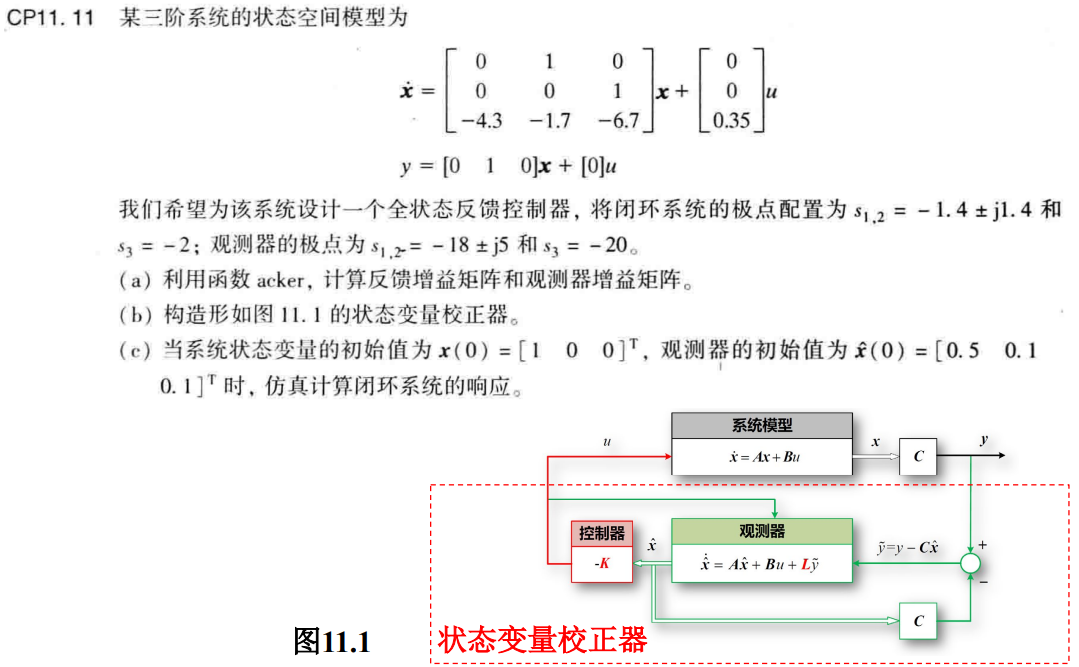

clear
clf

A=[0 1 0;0 0 1;-4.3 -1.7 -6.7]; B=[0;0;0.35]; C=[0 1 0]; D=[0];
p=[-1.4+1.4*j;-1.4-1.4*j;-2];
K=acker(A,B,p)
%b
q=[-18+5*j;-18-5*j;-20];
L = acker(A',C',q); L=L'
%c
Ac=[A -B*K;L*C A-B*K-L*C]; 
Bc=[zeros(6,1)];
Cc=eye(6); 
Dc=zeros(6,1);
sys=ss(Ac,Bc,Cc,Dc); 
x0=[1;0;0;0.5;0.1;0.1]; t=[0:0.001:3.5];
[y,t]=initial(sys,x0,t);
subplot(311)
plot(t,y(:,1),t,y(:,4),'--'), grid
subplot(312)
plot(t,y(:,2),t,y(:,5),'--'), grid
subplot(313)
plot(t,y(:,3),t,y(:,6),'--'), grid

# 13-1

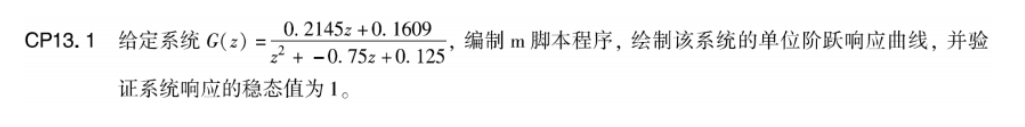

clear
clf

num=[0.2145 0.1609]; den=[1 -0.75 0.125];
sysd = tf(num,den,1);
t=[0:1:50];
step(sysd,t)

# 13-2

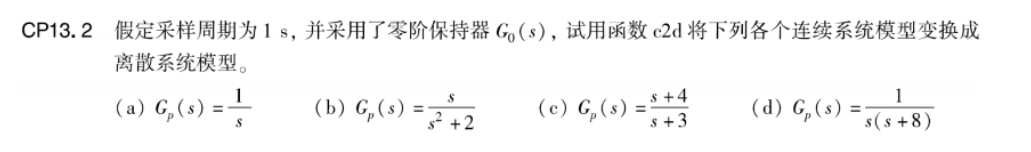

clear
clf
%a
num = [1]; den = [1 0]; T = 1;
sys = tf(num,den);
sys_d = c2d(sys,T,'zoh')
%b
num = [1 0]; den = [1 0 2]; T = 1;
sys = tf(num,den);
sys_d=c2d(sys,T,'zoh')
%c
num = [1 4]; den = [1 3]; T = 1;
sys = tf(num,den);
sys_d = c2d(sys,T,'zoh')
%d
num = [1]; den = [1 8 0]; T = 1;
sys = tf(num,den);
sys_d = c2d(sys,T,'zoh')

# 13-3

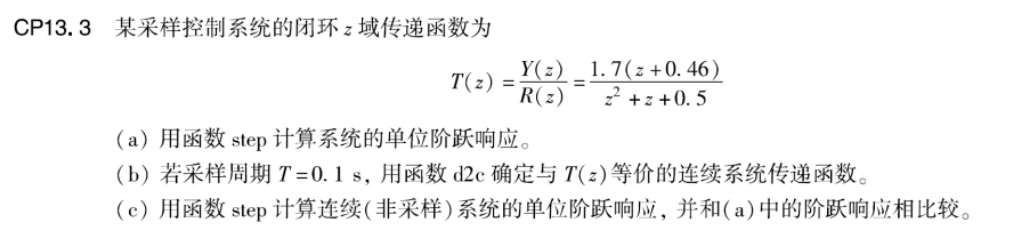

clear
clf
% (a)
num = 1.7 * [1 0.46]; den = [1 1 0.5];
T = 1;
t = 0:1:20;
sysd = tf(num,den,T);
step(sysd, t)
% (b)
num = 1.7 * [1 0.46]; den = [1 1 0.5];
T = 0.1;
t = 0:0.1:2;
sysd = tf(num,den,T);
sys = d2c(sysd)
% (c)
step(sys, t)